sm = SessManager;

mkdir converted_events

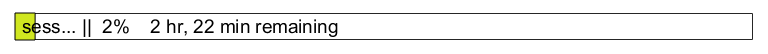

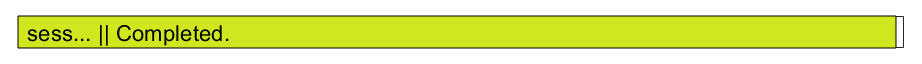

progressbar('sess...');
for i = 1:sm.num_usable
    d = sm.cons_usable(i);
    sp = d.source_path;

    top_dir = 'converted_events';
    target_file = fullfile(top_dir, sp(19:end));

    ET = load(sp);
    tracesEvents = struct;
    tracesEvents.position = ET.tracesEvents.position;

    T = 1;
    Fs = 20;
    gamma_sample_times = linspace(0,5,T * Fs + 1);
    gamma_sample_times = gamma_sample_times(2:end);
    gamma = @(t) t.*exp(1-t);
    transient_profile = gamma(gamma_sample_times);
    transient_profile = transient_profile(:);
    X =...
        hyperdetect(ET.tracesEvents.rawTraces, 'z_val', 3, 'Progress', false, 'OutType', 'onset');
    X_ = conv2(X, transient_profile, 'full');
    X_ = X_(1:size(X,1),:);
    X = X_;
    X = X ./ (std(X) + eps);
    tracesEvents.events_transients = X;
    mkdir(fileparts(target_file));
    save(target_file, 'tracesEvents');
    progressbar(i/sm.num_usable);
end

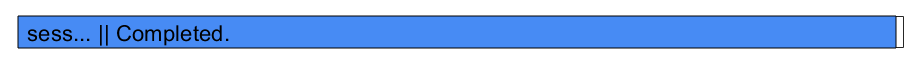

progressbar('sess...');
for i = 1:sm.num_usable
    d = sm.cons_usable(i);
    sp = d.source_path;

    top_dir = 'converted_events';
    target_file = fullfile(top_dir, sp(19:end));

    ET = load(sp);
    
    ET2 = load(target_file);
    ET2.tracesEvents.rawTraces = ET.tracesEvents.rawTraces;
    
    tracesEvents = ET2.tracesEvents;
    save(target_file, 'tracesEvents');
    progressbar(i/sm.num_usable);
end

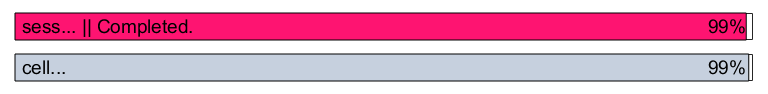

progressbar('sess...', 'cell...');
%sum_tr = 0;
%sum_ev = 0;
all_tr  = cell(sm.num_usable, 1);
counter = 0;
for i = 1:sm.num_usable
    pth = sm.cons_usable(i, true);
    pth = pth{1};
    
    target_file = fullfile(top_dir, sp(19:end));
    
    ET = load(target_file);
    
    ev = ET.tracesEvents.events_transients;
    tr = ET.tracesEvents.rawTraces;
    [n_frames, n_cells] = size(tr);
    %counter = counter + n_cells; progressbar(i/sm.num_usable, []); continue;
    for j = 1:n_cells
        my_tr = tr(:,j);
        my_ev = ev(:,j);
        
        onsets = my_ev ~= 0;
        onsets = [false ; diff(onsets) == 1];
        onsets = find(onsets);
        for k = 1:numel(onsets)
            my_onset = onsets(k);
            pre_frames = 20;
            post_frames = 80;
            
            my_range = my_onset - pre_frames : my_onset + post_frames;
            my_range = min(n_frames,max(1, my_range));
            
            %all_tr = [all_tr ; tr(my_range)];
            counter = counter + 1;
            all_tr{i}{j}{k} = tr(my_range);
            %sum_tr = sum_tr + tr(my_range);
            %sum_ev = sum_ev + ev(my_range);
            
        end
        progressbar([], j/n_cells);
    end
    progressbar(i/sm.num_usable, []);
end


%mean_tr = sum_tr / counter;
%mean_ev = sum_ev / counter;

all_tr = [all_tr{:}];
all_tr = cat(2, all_tr{:});

Error using cat
Dimensions of arrays being concatenated are not consistent.

all_tr = cell2mat(all_tr.');

mean_tr = mean(all_tr, 1);
std_tr = std(all_tr, 0, 1);
sem_tr = std_tr ./ sqrt(size(all_tr,1));

figure;
fr = seconds((-pre_frames:post_frames)/20);

Unrecognized function or variable 'pre_frames'.

serrorbar(fr, mean_tr, sem_tr); hold on;


gamma = @(t) t.*exp(1-t);
T = 1.5;
Fs = 20;
gamma_sample_times = linspace(0,7.5,T * Fs + 1);
gamma_sample_times = gamma_sample_times(2:end);
gamma_values = gamma(gamma_sample_times);

%plot(fr, mean_ev);
stem(seconds(gamma_sample_times / 7.5 * T), gamma_values .* max(mean_tr));
xlabel 'Time (s)'
ylabel 'Event triggered average'
%legend rawTraces transient location best

For one session only:

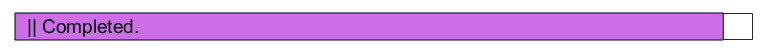

pth = sm.cons_usable(69, true);
pth = pth{1};

target_file = fullfile(top_dir, sp(19:end));

ET = load(target_file);

ev = ET.tracesEvents.events_transients;
tr = ET.tracesEvents.rawTraces;
[n_frames, n_cells] = size(tr);
%counter = counter + n_cells; progressbar(i/sm.num_usable, []); continue;

counter_one = 0;
all_tr_one = cell(1,n_cells);

for j = 1:n_cells
    my_tr = tr(:,j);
    my_ev = ev(:,j);

    onsets = my_ev ~= 0;
    onsets = [false ; diff(onsets) == 1];
    onsets = find(onsets);
    for k = 1:numel(onsets)
        my_onset = onsets(k);
        pre_frames = 20;
        post_frames = 80;

        my_range = my_onset - pre_frames : my_onset + post_frames;
        my_range = min(n_frames,max(1, my_range));

        %all_tr = [all_tr ; tr(my_range)];
        counter_one = counter_one + 1;
        all_tr_one{j}{k} = tr(my_range);
        %sum_tr = sum_tr + tr(my_range);
        %sum_ev = sum_ev + ev(my_range);

    end
    progressbar(j/n_cells);
end

all_tr_one = cell2mat([all_tr_one{:}].');
mean_tr_one = mean(all_tr_one, 1);
std_tr_one = std(all_tr_one, 0, 1);
sem_tr_one = std_tr_one ./ sqrt(size(all_tr_one,1));

figure;
fr = seconds((-pre_frames:post_frames)/20);

Unrecognized function or variable 'pre_frames'.

serrorbar(fr, mean_tr_one, sem_tr_one); hold on;


gamma = @(t) t.*exp(1-t);
T = 1.5;
Fs = 20;
gamma_sample_times = linspace(0,7.5,T * Fs + 1);
gamma_sample_times = gamma_sample_times(2:end);
gamma_values = gamma(gamma_sample_times);

%plot(fr, mean_ev);
stem(seconds(gamma_sample_times / 7.5 * T), gamma_values .* max(mean_tr));
xlabel 'Time (s)'
ylabel 'Event triggered average'